Application 1

2+3

ans = 5

2.^3 + 2^2

ans = 12

((3+2)*(3-2)) +(4+2)

ans = 11

Application 2

X = 2;
Y = 3;
Z= X + Y

Z = 5

Appplication 3

X1=5;
Y1=10;
Z1=X1+Y1

Z1 = 15

Application4 

who


Your variables are:

C            J            K            L            M            R2           RParallele1  Re1          S            V            Vc           Vg           X            X1           X2           X3           X5           X6           Y            Y1           Z            Z1           a            ans          b            courant      dydt         f            g            p            pks          r1           r2           r3           r4           r5           r6           r7           rP2          re           re1          resistance   result       resultat     rp1          rp2          rtotale      s            t            t1           tension      tensionInv   x            x1           xmax         xmin         y            



whos

  Name              Size            Bytes  Class              Attributes

  C                 1x1                 8  double                       
  J                 1x1                 8  sym                          
  K                 1x1                 8  sym                          
  L                 1x1                 8  sym                          
  M                 1x1                 8  sym                          
  R2                1x1                 8  double                       
  RParallele1       1x1                 8  double                       
  Re1               1x1                 8  double                       
  S                 1x1                 8  sym                          
  V                 1x1                 8  sym                          
  Vc               53x1               424  double                       
  Vg                1x1                 8  double                       
  X                 1x1                 8  double 

help clc

 clc - Clear Command Window
    This MATLAB function clears all the text from the Command Window,
    resulting in a clear screen.

    Syntax
      clc

    Examples
      Clear All Output

    See also clear, clf, close, home

    Introduced in MATLAB before R2006a
    Documentation for clc



Appplication 5

x = 1

x = 1

log(x)

ans = 0

log10(x)

ans = 0

exp(x)

ans = 2.7183

x = -1

x = -1

abs(x)

ans = 1

sign(x)

ans = -1

Appplication 6

x = 1.28

x = 1.2800

round(x)

ans = 1

floor(x)

ans = 1

ceil(x)

ans = 2

fix(x)

ans = 1

x1 = -1.28

x1 = -1.2800

fix(x1)

ans = -1

Appplication 7

x = 90

x = 90

cos(x)

ans = -0.4481

sin(x)

ans = 0.8940

tan(x)

ans = -1.9952

Les resultats obtenus ne conforment pas aux attentes car matlab ne reconnait pas x comme etant un degre mais comme un nombre, pour regler ce problem, nous allons ajouter la lettre d aux fonctions de trigonometrie

cosd(x)

ans = 0

sind(x)

ans = 1

tand(x)

ans = Inf

Appplication 8

% calculer la valeur de l'intégrale à 2*pi/3. 
x = 2*pi/3;
y = myIntegrand(x)

y = 0.6495

% calculer l'aire sous la courbe de 0 à π xmin = 0;
xmin = 0;
xmax = pi;
f = @myIntegrand;
a = integral(f,xmin,xmax)

a = 1.3333

function y = myIntegrand(x)
    y = sin(x).^3;
end

Nombre Complexes

a=1+ 1i;
b=1- 1j;
2*a+b

ans = 3.0000 + 1.0000i

2*a - b

ans = 1.0000 + 3.0000i

a*b

ans = 2

a/b

ans = 0.0000 + 1.0000i

conj(a)

ans = 1.0000 - 1.0000i

conj(b)

ans = 1.0000 + 1.0000i

abs(a)

ans = 1.4142

abs(b)

ans = 1.4142

angle(a+b)

ans = 0

angle(a-b)

ans = 1.5708

real(a)

ans = 1

real(b)

ans = 1

imag(a+b)

ans = 0

Calculs Limite

syms x
f = sin(x)/x

$$f = \frac{\sin\left(x\right)}{x}$$

L= limit(f,x,0);
display(L)

$$L = 1$$


syms x
S = 1/(2*x-6)

$$S = \frac{1}{2\,x-6}$$

M = limit(S,x,3)

$$M = \mathrm{NaN}$$

display(M)

$$M = \mathrm{NaN}$$


syms x
Z1 = x/(-4 + 2*x)

$$Z1 = \frac{x}{2\,x-4}$$

V = limit(Z1,x,-2)

$$V = \frac{1}{4}$$

display(V)

$$V = \frac{1}{4}$$


syms x
J = sqrt(2*x) +1 - 2*x/x

$$J = \sqrt{2}\,\sqrt{x}-1$$

K = limit(J,x, inf)

$$K = \infty$$

display(K)

$$K = \infty$$

Tracer des graphes

tension = 0:2.5:25; % V
resistance = 10; % Ohms
courant = tension / resistance;
plot(courant,tension, "MAGENTA")
xlabel courant
ylabel tension
t = title ("La tension en Fonction du courant")

t =   Text (La tension en Fonction du courant) with properties:

                 String: 'La tension en Fonction du courant'
               FontSize: 11
             FontWeight: 'bold'
               FontName: 'Helvetica'
                  Color: [0 0 0]
    HorizontalAlignment: 'center'
               Position: [1.2500 25.1931 1.4211e-14]
                  Units: 'data'

  Show all properties


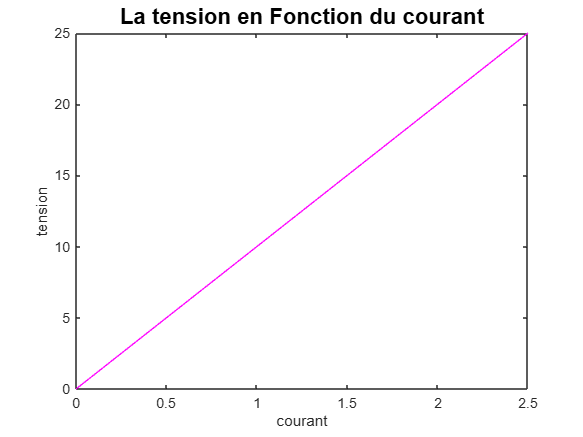

t.FontSize = 16;

Le Courant en Fonction de la Tension

courant = 0:10:20; % mA
resistance = 10; % Ohms
tension = courant * resistance;
plot(tension,courant, "RED")
xlabel tension
ylabel courant
t = title ("Le Courant en Fonction de la Tension")

t =   Text (Le Courant en Fonction de la Tension) with properties:

                 String: 'Le Courant en Fonction de la Tension'
               FontSize: 11
             FontWeight: 'bold'
               FontName: 'Helvetica'
                  Color: [0 0 0]
    HorizontalAlignment: 'center'
               Position: [100.0001 20.1545 1.4211e-14]
                  Units: 'data'

  Show all properties


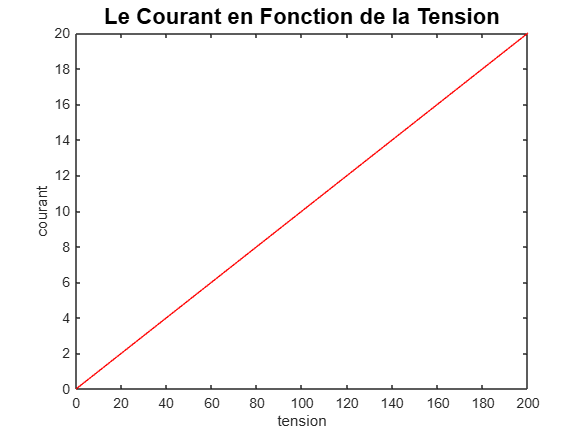

t.FontSize = 16;

Find Max Min

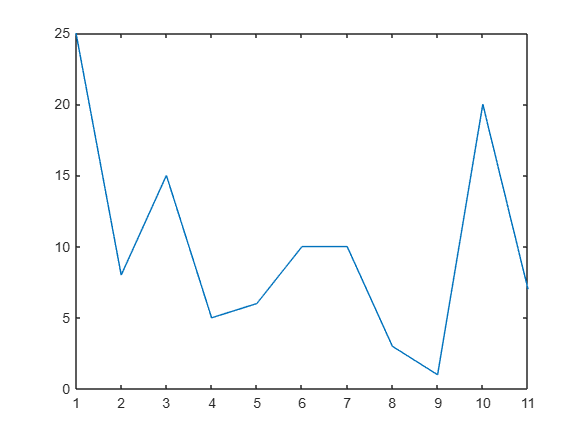

tension = [25 8 15 5 6 10 10 3 1 20 7];
plot(tension);

pks = findpeaks(tension);
display(pks);

pks =     15    10    20


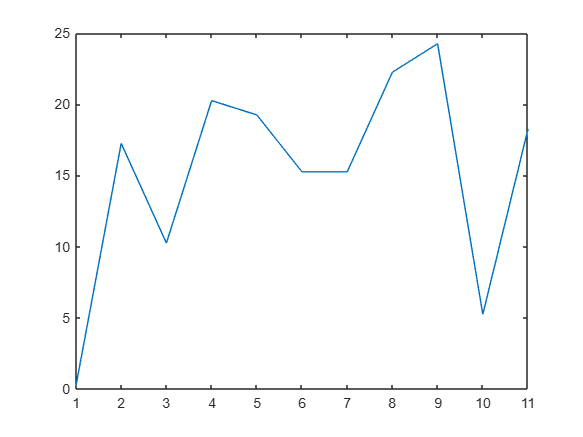

tensionInv = 1.01*max(tension) - tension; 
plot(tensionInv);

pks = findpeaks(tensionInv);
display(pks);

pks =    17.2500   20.2500   24.2500


Resistance Equivalentes

r1 = 200;
r2 = 50;
r3 = 150;
r4 = 800;
r5 = 100;
r6 = 300;
RParallele1 = 1/(1/r2+1/r3);
Re1 = RParallele1 + r1;
rP2 = 1/(1/Re1 + 1/r4);
rtotale = rP2 + r5 + r6;
display(rtotale)

rtotale = 583.1325

Application 14: Puissance dissipee

r1 = 100;
r2 = 200;
r3 = 100;
r4 = 800;
r5 = 150;
r6 = 50;
r7 = 50;
rp1 = 1/(1/r7+1/r6);
re1 = rp1 + r4 + r5;
rp2 = 1/(1/re1+ 1/r2);
re = rp2 + r1 +r3;
display (re)

re = 365.9574

resultat = tension/re;
display (result);

result = 1.0e+03 *

    8.6818    2.7782    5.2091    1.7364    2.0836    3.4727    3.4727    1.0418    0.3473    6.9455    2.4309


la puissance dissipée par la résistance équivalente 

t1 =sort(tension);

p = (t1).^2/re

p =     0.0027    0.0246    0.0683    0.0984    0.1339    0.1749    0.2733    0.2733    0.6148    1.0930    1.7078


disp(p)

    0.0027    0.0246    0.0683    0.0984    0.1339    0.1749    0.2733    0.2733    0.6148    1.0930    1.7078



**Tracer sur Matlab la puissance dissipée par la résistance Réquivalente en fonction de la tension**

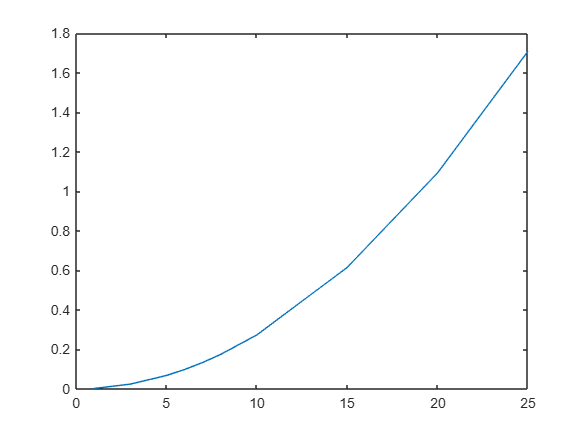

plot(t1,p)

**Symbolic Math Toolbox**

syms s x y
g(x) = sin(x)/x

$$g(x) = \frac{\sin\left(x\right)}{x}$$

laplace(g(x))

$$ans = \mathrm{atan}\left(\frac{1}{s}\right)$$

ilaplace(atan(1/s))

$$ans = \frac{\sin\left(t\right)}{t}$$

comment : ilaplce donne l'inverse de laplace

syms x
	g(x)=sin(x)/x

$$g(x) = \frac{\sin\left(x\right)}{x}$$

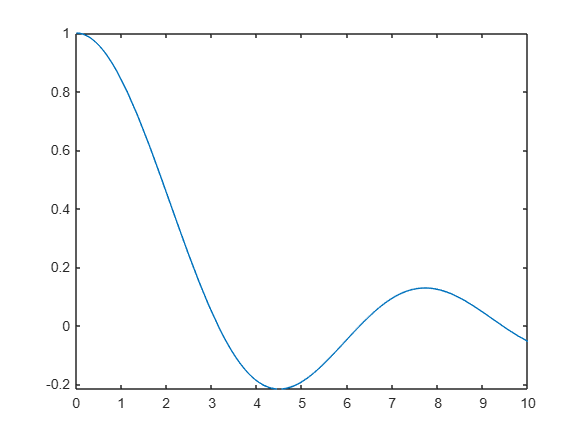

	% Tracer g(x)
	fplot(g,[0,10])

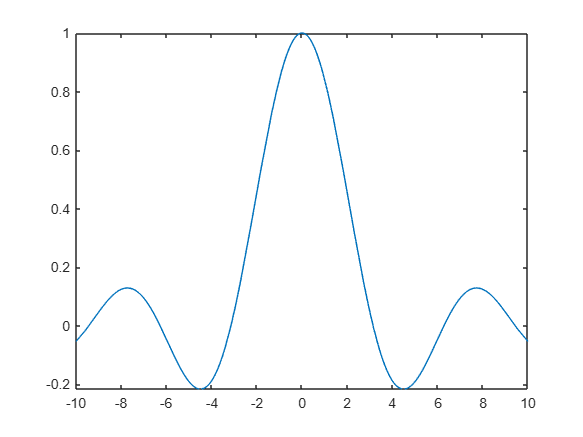

	fplot(g, [-10,10])

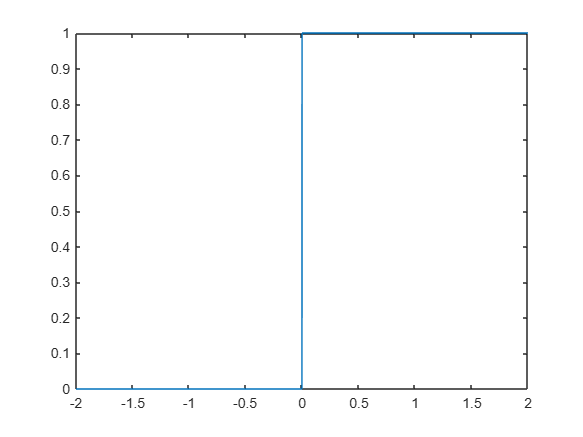

    syms x
	fplot(heaviside(x), [-2, 2])

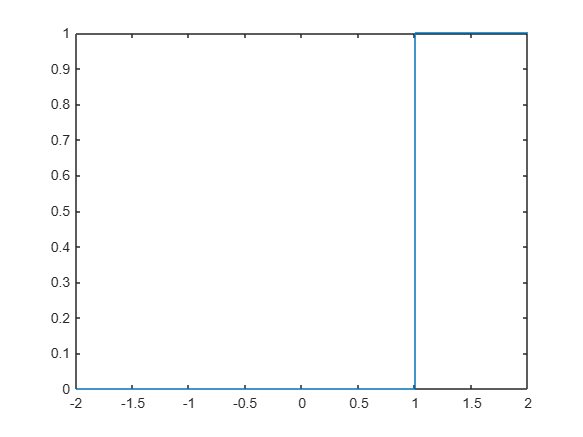

	fplot(heaviside(x-1), [-2, 2])

 En utilisant la loi des mailles, déterminez la relation entre la tension et courant : vs = vr + vc => Vs/RC = dVc/dt + Vc/RC

 Déterminer l’expression de l’équation différentielle entre  dv/dt et vc => .1/R(dVs/dt) = dI(t)/dt + 1/RC

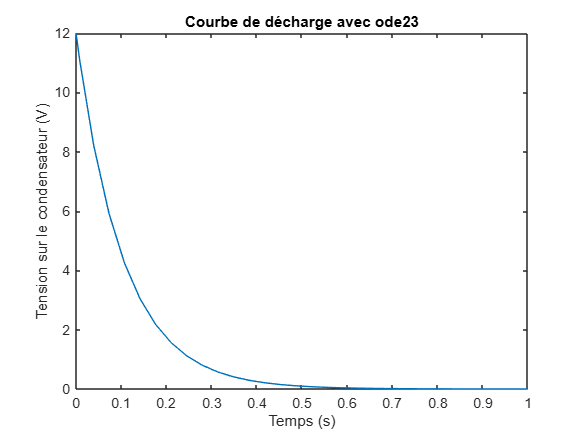


R2 = 2.2e3; 
C = 47e-6; 
Vg = 12; 


dydt = @(t, Vc) -1/(R2*C) * Vc;

[t, Vc] = ode23(dydt, [0, 1], Vg);


plot(t, Vc);
title('Courbe de décharge avec ode23');
xlabel('Temps (s)');
ylabel('Tension sur le condensateur (V)');

Répéter l’étape c mais en utilisant cette fois la fonction ode45

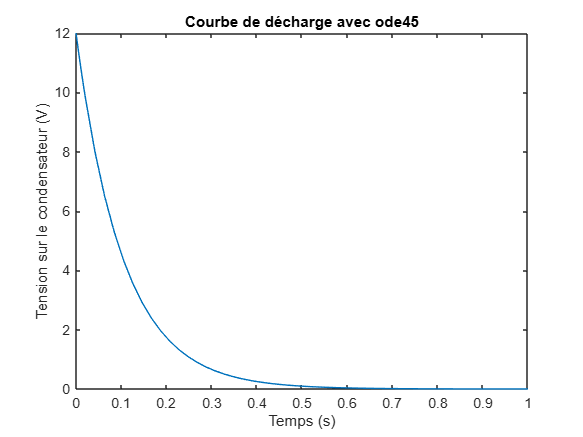

[t, Vc] = ode45(dydt, [0, 1], Vg);

plot(t, Vc);
title('Courbe de décharge avec ode45');
xlabel('Temps (s)');
ylabel('Tension sur le condensateur (V)');

 **Comparaison des résultats** : Les deux fonctions `ode23` et `ode45` utilisent des méthodes numériques différentes pour résoudre l'équation différentielle. `ode23` est basé sur une méthode d'ordre inférieur, tandis que `ode45` utilise une méthode d'ordre supérieur (Runge-Kutta d'ordre 4-5), ce qui peut fournir une précision différente. Dans ce cas, les résultats devraient être très similaires puisque l'équation est simple, mais `ode45` pourrait être plus précis pour des intervalles de temps plus longs ou des équations plus complexes.